# Edge Detection on Images

This example shows how to generate a standalone C library from MATLAB code that implements a simple Sobel filter that performs edge detection on images. The example also shows how to generate and test a MEX function in MATLAB prior to generating C code to verify that the MATLAB code is suitable for code generation.

## About the `sobel` Function

The `sobel.m` function takes an image (represented as a double matrix) and a threshold value and returns an image with the edges detected (based on the threshold value).

type sobel


% edgeImage = sobel(originalImage, threshold)
% Sobel edge detection. Given a normalized image (with double values)
% return an image where the edges are detected w.r.t. threshold value.
function edgeImage = sobel(originalImage, threshold) %#codegen
assert(all(size(originalImage) <= [1024 1024]));
assert(isa(originalImage, 'double'));
assert(isa(threshold, 'double'));

k = [1 2 1; 0 0 0; -1 -2 -1];
H = conv2(double(originalImage),k, 'same');
V = conv2(double(originalImage),k','same');
E = sqrt(H.*H + V.*V);
edgeImage = uint8((E > threshold) * 255);


## Generate the MEX Function

Generate a MEX function using the `codegen` command.

codegen sobel


Code generation successful (with warnings): View report


Before generating C code, you should first test the MEX function in MATLAB to ensure that it is functionally equivalent to the original MATLAB code and that no run-time errors occur. By default, `codegen` generates a MEX function named `sobel_mex` in the current folder. This allows you to test the MATLAB code and MEX function and compare the results.

## Read in the Original Image

Use the standard `imread` command.

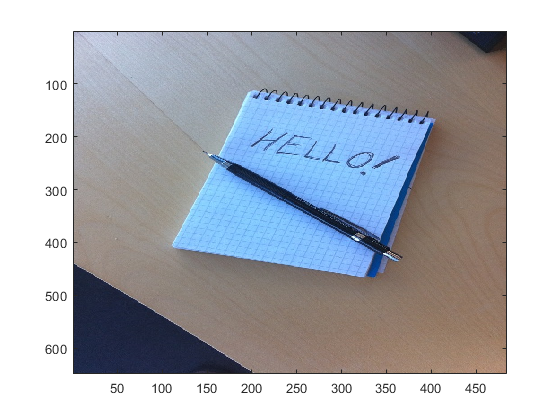

im = imread('hello.jpg');
image(im);

## Convert Image to a Grayscale Version

Convert the color image (shown above) to an equivalent grayscale image with normalized values (0.0 for black, 1.0 for white).

gray = (0.2989 * double(im(:,:,1)) + 0.5870 * double(im(:,:,2)) + 0.1140 * double(im(:,:,3)))/255;

## Run the MEX Function (The Sobel Filter)

Pass the normalized image and a threshold value.

edgeIm = sobel_mex(gray, 0.7);

## Display the Result

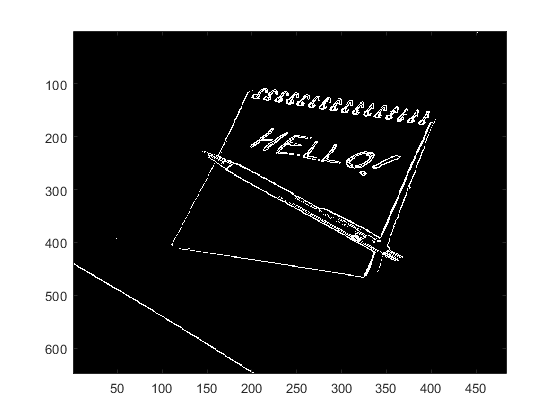

im3 = repmat(edgeIm, [1 1 3]);
image(im3);

## Generate Standalone C Code

codegen -config coder.config('lib') sobel


Code generation successful (with warnings): View report


Using `codegen` with the `-config coder.config('lib')` option produces a standalone C library. By default, the code generated for the library is in the folder `codegen/lib/sobel/`.

## Inspect the Generated Function

type codegen/lib/sobel/sobel.c


/*
 * Academic License - for use in teaching, academic research, and meeting
 * course requirements at degree granting institutions only.  Not for
 * government, commercial, or other organizational use.
 * File: sobel.c
 *
 * MATLAB Coder version            : 4.1
 * C/C++ source code generated on  : 14-Mar-2019 21:04:51
 */

/* Include Files */
#include "sobel.h"
#include "sobel_emxutil.h"
#include "sqrt.h"
#include "conv2.h"

/* Function Definitions */

/*
 * Arguments    : const emxArray_real_T *originalImage
 *                double threshold
 *                emxArray_uint8_T *edgeImage
 * Return Type  : void
 */
void sobel(const emxArray_real_T *originalImage, double threshold,
           emxArray_uint8_T *edgeImage)
{
  emxArray_real_T *H;
  emxArray_real_T *V;
  int i0;
  int loop_ub;
  emxInit_real_T(&H, 2);
  emxInit_real_T(&V, 2);

  /*  edgeImage = sobel(originalImage, threshold) */
  /*  Sobel edge detection. Given a normalized image (with double values) */
  /*  return an

*Copyright 2018 The MathWorks, Inc.*